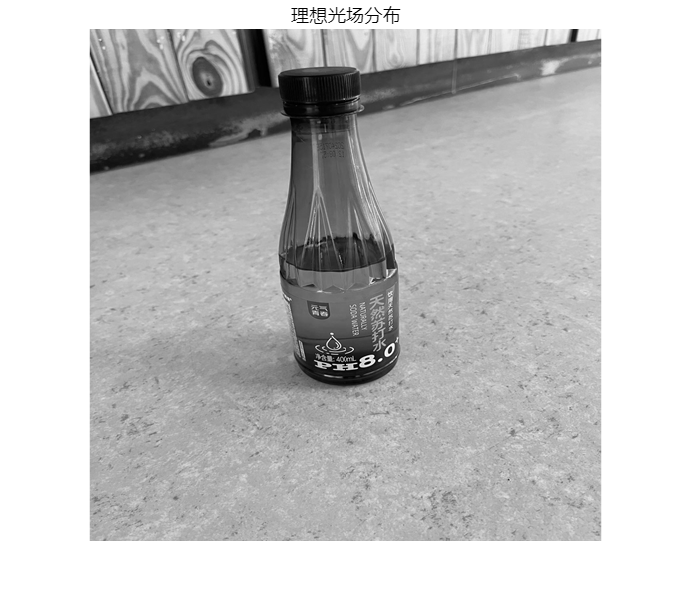

clc;
clear;
close all;
% GS算法 远场
% 假设输入图像为512×512像素，256灰度级的灰度图
maxn = 200;% 设置迭代次数
img = imread('C:\Users\86152\Desktop\视觉科学-hhy\512像素点.png'); % 读取彩色图像
%imshow(img);
Im = rgb2gray(img); % 将彩色图像转换为灰度图像

% 将灰度图像归一化到0-255范围
%Im = (double(grayImg) / double(max(grayImg(:)))) * 255;
Im=double(Im);
im_original = Im./max(max(Im));
figure()
imshow(im_original,[]); % 显示256级灰度图像
imwrite(im_original,'C:\Users\86152\Desktop\视觉科学-hhy\灰白.png','png');
title('理想光场分布');

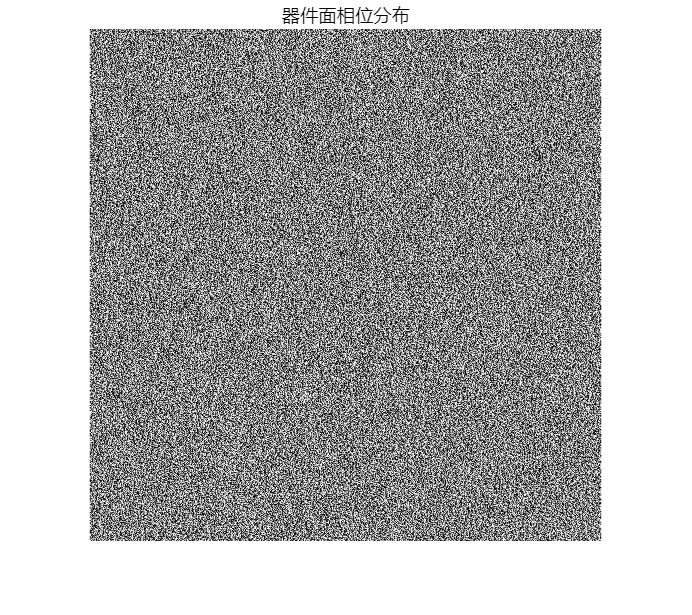


% im_hologram表示全息面的图像，im_image表示成像面图像
im_image = im_original.*exp(2i*pi*rand(size(im_original)));% 加入随机相位
for n = 1:maxn % 迭代到指定次数结束
    % 反向传播计算全息图
    im_hologram = ifft2(ifftshift(im_original.*exp(1i*angle(im_image))));
    % 取全息图相位，振幅全部置一，模拟正向传播，计算像面图像
    im_image = fftshift(fft2(exp(1i*angle(im_hologram))));
end
angle_hologram = angle(im_hologram);
% 相位全息图显示
figure()
imshow(angle_hologram, [-pi,pi]);
img255=uint8((angle_hologram+pi)/2/pi*255);
imwrite(img255,'C:\Users\86152\Desktop\视觉科学-hhy\器件面相位分布.png','png');
title('器件面相位分布');

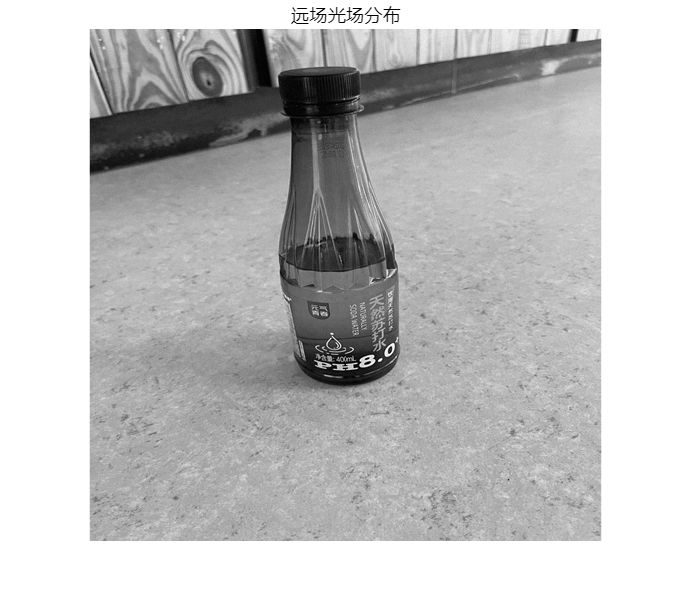


% 关闭当前图形窗口
% 光场归一化
im_field = abs(fftshift(fft2(exp(1i*angle(im_hologram)))));
im_field = (im_field -min(min(im_field)))/(max(max(im_field)) -min(min(im_field)));
% 全息像显示y
figure()
imshow(im_field);
title('远场光场分布');

imwrite(im_field, 'C:\Users\86152\Desktop\视觉科学\远场光场分布.png','png');

错误使用 imwrite
无法打开要写入的文件 "C:\Users\86152\Desktop\视觉科学\远场光场分布.png"。您可能没有写入权限。